%{
ES115 Engineering Computer Applications 
Module 1 Project: Cooling Curve Approximation

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 26, 2026

Purpose:
The purpose of this project is to analyze the cooling profile of a material by 
tracking temperature over time. Using MATLAB, the script calculates the rate of heat 
loss through finite differences and determines the total thermal exposure via numerical 
integration to assess heat dissipation efficiency.

Inputs:
- Time Vector (t): 0 to 20 minutes
- Step Size: 2 minutes
- Temperature Data (T): 11 discrete decreasing values representing the cooling process

Outputs:
- Rate of Change (dT/dt): Vector representing the cooling speed between samples
- Thermal Exposure: Total area under the temperature curve
- Visualizations: Subplots of temperature decay and cooling rate

Engineering Workflows:
- Thermal Analysis: Monitoring system state changes over time
- Numerical Differentiation: Approximating the derivative (cooling rate) from discrete data
- Numerical Integration: Using the trapezoidal rule to calculate cumulative exposure

MATLAB Tools:
- diff(): Calculating differences between adjacent elements for rate estimation
- trapz(): Performing numerical integration to find the area under the curve
- subplot(): Organizing multiple related graphs into a single figure
- plot(): Visualizing the relationship between time, temperature, and rates
%}


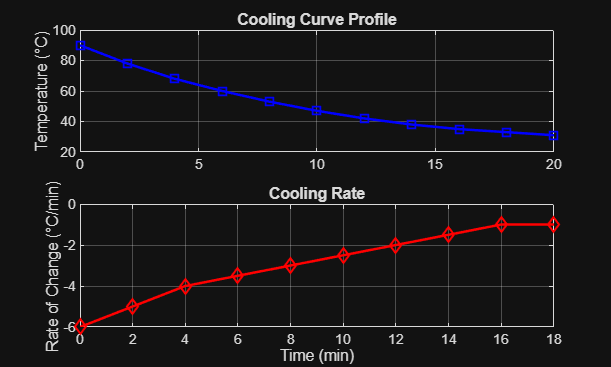

t = 0:2:20;
T = [90, 78, 68, 60, 53, 47, 42, 38, 35, 33, 31]; 

figure;
subplot(2,1,1);
plot(t, T, 'b-s', 'LineWidth', 1.5);
grid on;
ylabel('Temperature (°C)');
title('Cooling Curve Profile');

dT_dt = diff(T) ./ diff(t);
t_mid = t(1:end-1);

subplot(2,1,2);
plot(t_mid, dT_dt, 'r-d', 'LineWidth', 1.5);
grid on;
xlabel('Time (min)');
ylabel('Rate of Change (°C/min)');
title('Cooling Rate');


total_exposure = trapz(t, T);

fprintf('Total Thermal Exposure: %.2f °C-min\n', total_exposure);

Total Thermal Exposure: 1029.00 °C-min
